# Nombre de condició - ben condicionat - mal condicionat

#### Matriu ben condicionat

A = [8 -5; 4 10]; b = [3; 14]; x = A\b

x =      1
     1


db = [-0.04; -0.06]; xm= A\(b+db)

xm =     0.9930
    0.9968


%canvi relatiu en la solucio per el canvi dn el terme independent
norm(db)/norm(b)*100 %canvi relatiu en el terme independent

ans = 0.5036

norm(x-xm)/norm(x)*100 %canvi relatiu en la solucio

ans = 0.5442

#### Matriu mal condicionat

A = [0.66 3.34; 1.99 10.01]; b = [4; 12]; x = A\b

x =     1.0000
    1.0000


db = [-0.04; -0.06]; xm= A\(b+db)

xm =     6.0000
    0.0000


%canvi relatiu en la solucio per el canvi dn el terme independent
norm(db)/norm(b)*100 %canvi relatiu en el terme independent

ans = 0.5701

norm(x-xm)/norm(x)*100 %canvi relatiu en la solucio

ans = 360.5551

#### Grafica

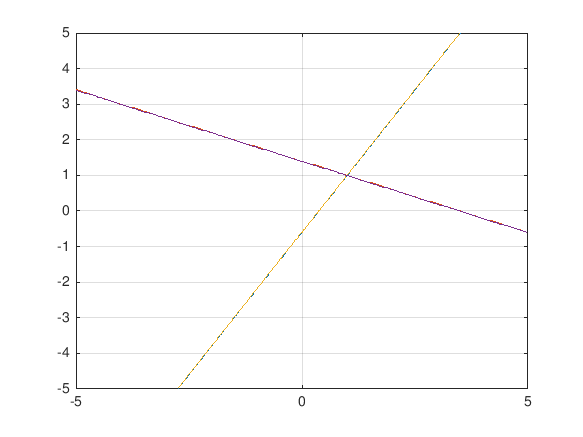

fimplicit(@(x,y)8*x-5*y-3)
hold on
fimplicit(@(x,y)4*x+10*y-14)
fimplicit(@(x,y)8*x-5*y-2.96)
fimplicit(@(x,y)4*x+10*y-13.94), grid
hold off

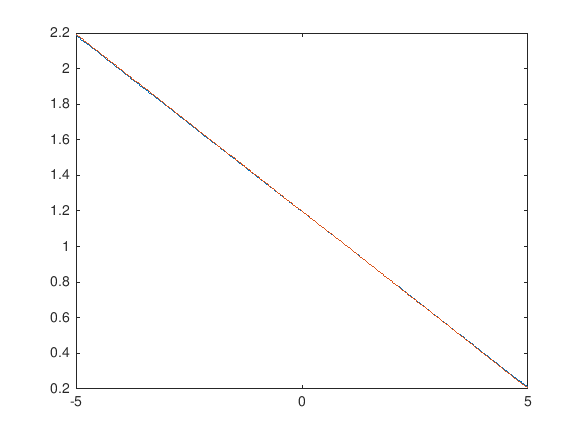

fimplicit(@(x,y)0.66*x+3.34*y-4)
hold on
fimplicit(@(x,y)1.99*x+10.01*y-12)  % Els dues equacions dibuixen casi la mateixa recta
hold off                            % El nombre de condicio medeix la sigularitat

A = [8 -5; 4 10]; condest(A), det(A)        %sistema compatible determinat

ans = 2.1000

ans = 100

A = [0.66 3.34; 1.99 10.01]; condest(A), det(A)         %sistema compatible casi indeterminat

ans = 4005

ans = -0.0400

A = eye(100)*0.1;
A(1,1) = 1;
det(A), rank(A), cond(A), condest(A), rcond(A)

ans = 1.0000e-99

ans = 100

ans = 10

ans = 10

ans = 0.1000

A = eye(50);
for i=1:49
    A(i, i+1)=2;
end
det(A), rank(A), cond(A), condest(A), rcond(A)

ans = 1

ans = 49

ans = 2.2508e+15

ans = 3.3777e+15

ans = 2.9606e-16